# 21.1

1. 

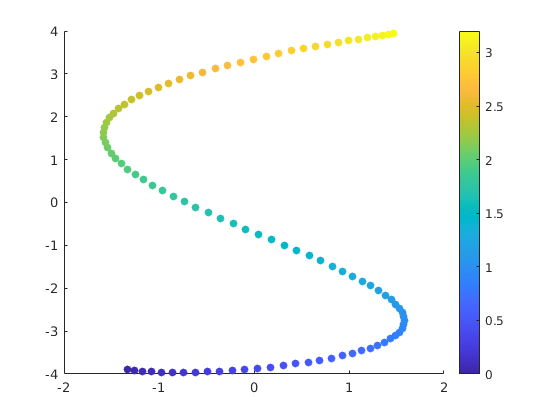

syms u
assume(u,["positive","real"])
r = 4 * [0.3960*cos(2.65 * (u + 1.4)); -0.99 * sin(u + 1.4); 0 * u];
r = simplify(r);

u_0 = 0;
u_max = 3.2;
u_num = linspace(u_0, u_max);
r_num = subs(r, u, u_num);
scatter(r_num(1, :), r_num(2, :), 36, u_num, "filled")
colorbar

2.

T_hat = simplify(diff(r,u)/norm(diff(r,u)));
N_hat = simplify(diff(T_hat,u)/norm(diff(T_hat,u)));
u_samples_indices = round(linspace(1, length(u_num), 5));
u_samples = u_num(u_samples_indices);
T_hat_samples = subs(T_hat, u, u_samples);
N_hat_samples = subs(N_hat, u, u_samples);

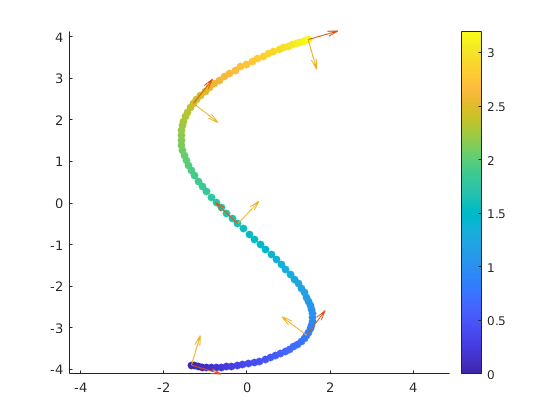

figure()
hold on
scatter(r_num(1, :), r_num(2, :), 36, u_num, "filled")
colorbar
quiver(r_num(1, u_samples_indices), r_num(2, u_samples_indices), T_hat_samples(1,:), T_hat_samples(2,:), 0.2)
quiver(r_num(1, u_samples_indices), r_num(2, u_samples_indices), N_hat_samples(1,:), N_hat_samples(2,:), 0.2)
axis equal

# 21.2

1.

syms beta t
assume([beta, t], "real")
r_t = subs(r, u, beta * t)

$$r\_t = \left(\begin{array}{c} \frac{198\,\cos\left(\frac{53\,\beta \,t}{20}+\frac{371}{100}\right)}{125}\\ -\frac{99\,\sin\left(\beta \,t+\frac{7}{5}\right)}{25}\\ 0 \end{array}\right)$$

vel = diff(r_t, t)

$$vel = \left(\begin{array}{c} -\frac{5247\,\beta \,\sin\left(\frac{53\,\beta \,t}{20}+\frac{371}{100}\right)}{1250}\\ -\frac{99\,\beta \,\cos\left(\beta \,t+\frac{7}{5}\right)}{25}\\ 0 \end{array}\right)$$

T_hat_t = subs(T_hat, u, beta*t);

vel_lin = dot(vel, T_hat_t)*T_hat_t;
vel_ang = cross(T_hat_t, diff(T_hat_t, t));

speed = norm(vel_lin);

sub_vals = struct();
sub_vals.beta = 0.5;
sub_vals.t = u_num/sub_vals.beta;

tspan = sub_vals.t;

speeds = subs(speed, sub_vals);
mat_omegas = eval(subs(vel_ang, sub_vals));
omegas = mat_omegas(3, :);

omegas =     1.3607    1.0879    0.8915    0.7493    0.6458    0.5705    0.5163    0.4783    0.4532    0.4389    0.4340    0.4375    0.4491    0.4689    0.4971    0.5346    0.5823    0.6418    0.7145    0.8027    0.9083    1.0333    1.1784    1.3425    1.5205    1.7016    1.8677    1.9952    2.0606    2.0494    1.9624    1.8158    1.6335    1.4384    1.2476    1.0708    0.9126    0.7735    0.6522    0.5468    0.4547    0.3737    0.3018    0.2371    0.1780    0.1233    0.0716    0.0220   -0.0265   -0.0749


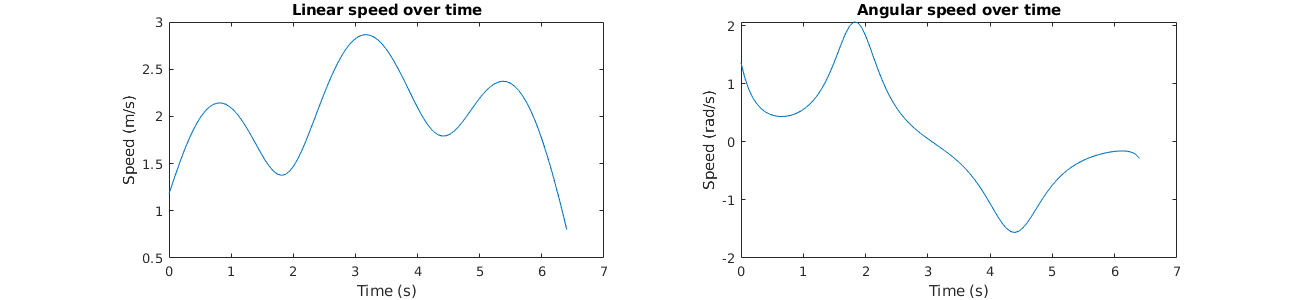

figure();
set(gcf, 'Position', [0, 0, 1300, 300])

subplot(1, 2, 1);
plot(tspan, speeds);
title("Linear speed over time")
xlabel("Time (s)")
ylabel("Speed (m/s)")

subplot(1, 2, 2);
plot(tspan, omegas);
title("Angular speed over time")
xlabel("Time (s)")
ylabel("Speed (rad/s)")